clear;
N = 1000;
m = 1;
n = 100;
X = randn(N, n);
W = randn(n, m);
Y = X * W + randn([N, m]) * 0.4;
X = X + randn([N, n]) * 0.4;

W_TLS = TLS(X, Y);
W_LS = LS(X, Y);
W_NNLS = NNLS(X, Y);

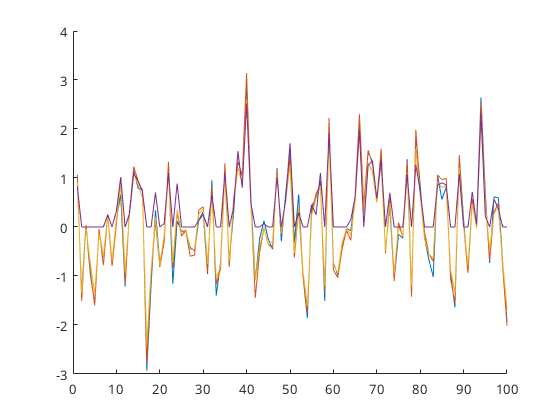

figure, hold on;
plot(W);
plot(W_TLS);
plot(W_LS);
plot(W_NNLS);
hold off;